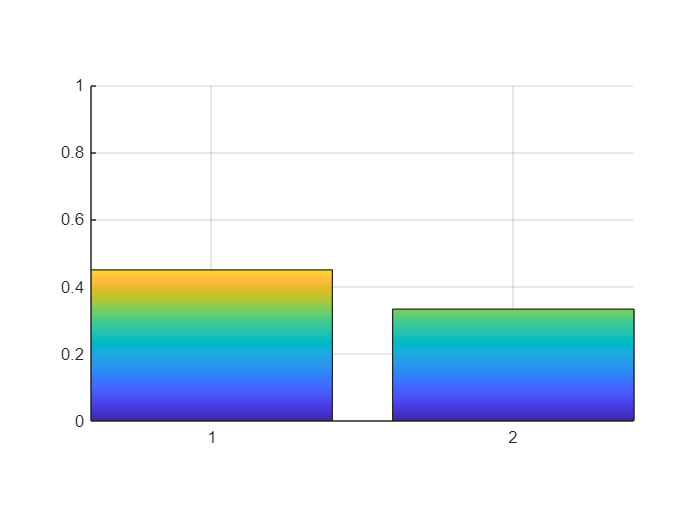

clearvars;
close all;

Length = 0.05;
wavelength = 0.00000155;
gap = 0.000006;
pm = 1e-12;
V = 1;
confinment_factor = 0.32;
no = 2.210;	
r33 = 30.8* pm/V;
RF_pi = (wavelength*gap)/((no^3)*confinment_factor*r33*Length);

i_bar = 1;
i_cross = 0;
RF_in = 1.7484;

kL_factor_s = pi*0.12;
kL_factor_c = pi*0.34;
alpha_1 = 0.2;
alpha_2 = 0.3;


Tc_matrix_s = [cos(kL_factor_s)     -1i*sin(kL_factor_s); 
               -1i*sin(kL_factor_s) cos(kL_factor_s)];
        
Tc_matrix_c = [(cos(kL_factor_c))    -1i*sin(kL_factor_c); 
               -1i*sin(kL_factor_c)  cos(kL_factor_c)];

loss_1 = (alpha_1*100/8.6860000037)*Length;
loss_2 = (alpha_2*100/8.6860000037)*Length;

dn=-(no^3)*r33*confinment_factor*RF_in/(2*gap);
d_phi = dn*(Length).*(2*pi/wavelength);
phi0 = no*(Length).*(2*pi/wavelength);

MC_matrix = [1*exp((-1i*(phi0+d_phi))-loss_1), 0; 0, 1*exp(-1i*(phi0)-loss_2)];
res = Tc_matrix_c*MC_matrix*Tc_matrix_s*[i_bar, i_cross]';

Intensity_input = (abs(i_bar)^2) + abs(i_cross)^2;
Intensity_fraction_bar = abs(res(1)^2)/Intensity_input;
Intensity_fraction_cross = abs(res(2)^2)/Intensity_input;

y = [Intensity_fraction_bar Intensity_fraction_cross];
b = bar3(y);
colormap default
b.FaceColor = "interp";
for a = 1:length(b)
    b(a).CData = b(a).ZData;
end
zlim([0 1])
clim([0 0.5])
view(-90,0)

Intensity_fraction_1 = sprintf('%.3f%%',Intensity_fraction_bar*100);
Intensity_fraction_2 = sprintf('%.3f%%',Intensity_fraction_cross*100); 

disp("Intensity output BAR : " + Intensity_fraction_1 + "        Intensity output CROSS : " + Intensity_fraction_2)

Intensity output BAR : 44.976%        Intensity output CROSS : 33.287%
